# Digital Signal Processing

# MATLAB HW - q1

Instructor: Professor Sheikhzadeh,  Author: Dina - Soltani Tehrani

E-mail: d.soltani.t@aut.ac.ir

Affiliation: Amirkabir University of Technology

# HW1-Q1

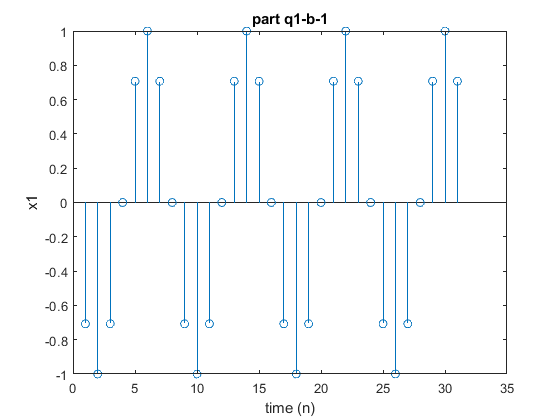

clc; clear; close;
x1=zeros(1,31);
u1= ones(1,31);
 for ii=1:31
    x1(1,ii)=cos(pi*(ii-6)/4) * u1(1,ii); 
 end
figure(1)
stem(x1)
xlabel('time (n)');
ylabel('x1');
title('part q1-b-1');

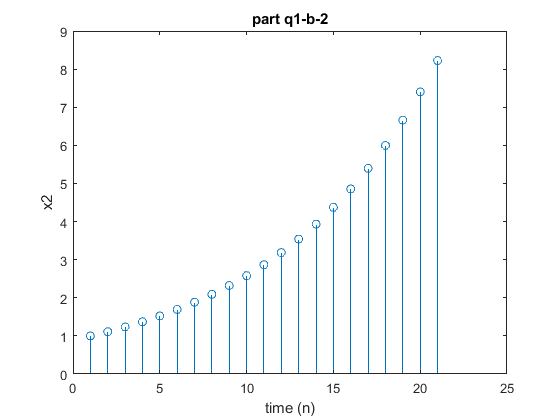

%--
x2=zeros(1,21);
u2= ones(1,21);
for ii=1:21
   x2(1,ii)=((0.9)^(-(ii-1)))* u2(1,ii) ; 
end
figure(2)
stem(x2)
xlabel('time (n)');
ylabel('x2');
title('part q1-b-2');

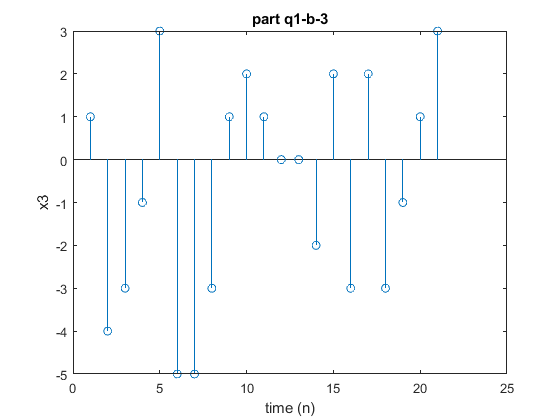

%--
Wn= -1 + 2.*rand(1,21);
x3= round(5* Wn);
figure(3)
stem(x3)
xlabel('time (n)');
ylabel('x3');
title('part q1-b-3');

## Commutation

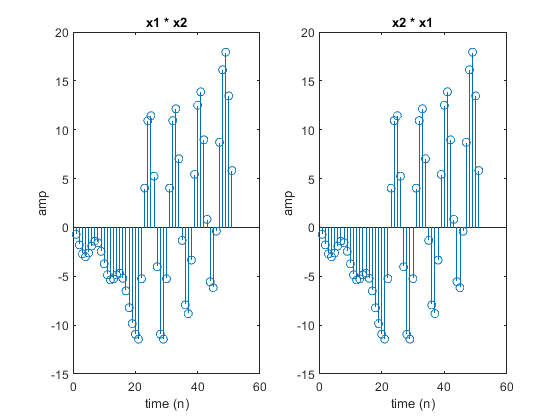

%-- Commutation
x41= conv(x1,x2);
x42= conv(x2,x1);
figure(4)
subplot(1,2,1)
stem(x41)
xlabel('time (n)');
ylabel('amp');
title('x1 * x2');
subplot(1,2,2)
stem(x42)
xlabel('time (n)');
ylabel('amp');
title('x2 * x1');

## Association

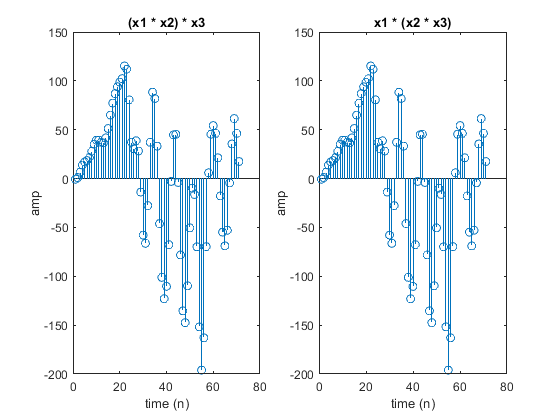

%-- Association
x51= conv( conv(x1,x2) , x3);
x52= conv( x1 , conv(x2,x3));
figure(5)
subplot(1,2,1)
stem(x51)
xlabel('time (n)');
ylabel('amp');
title('(x1 * x2) * x3');
subplot(1,2,2)
stem(x52)
xlabel('time (n)');
ylabel('amp');
title('x1 * (x2 * x3)');

## Distribution

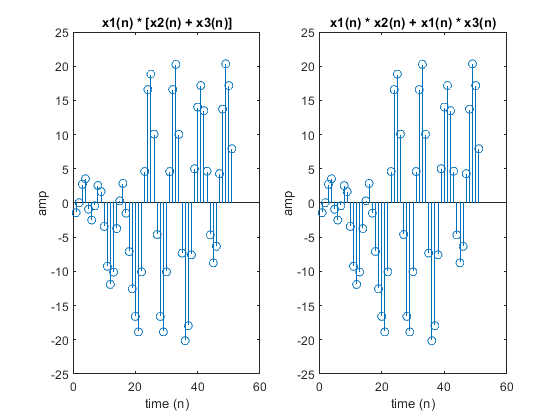

%-- Distribution
x61= conv( x1 , (x2 + x3));
x62= conv(x1,x2) + conv(x1,x3);
figure(6)
subplot(1,2,1)
stem(x61)
xlabel('time (n)');
ylabel('amp');
title('x1(n) * [x2(n) + x3(n)]');
subplot(1,2,2)
stem(x62)
xlabel('time (n)');
ylabel('amp');
title('x1(n) * x2(n) + x1(n) * x3(n)');

## Identity

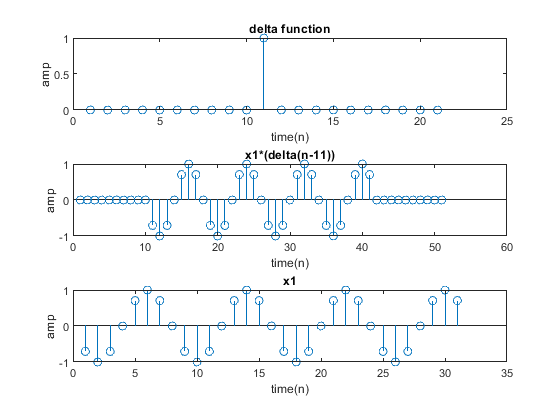

%-- Identity
figure(7)
xd=[zeros(1,10) 1 zeros(1,10)];
yd=conv(x1,xd);
subplot(3,1,1);stem(xd);xlabel('time(n)');ylabel('amp');title('delta function');
subplot(3,1,2);stem(yd);xlabel('time(n)');ylabel('amp');title('x1*(delta(n-11))');
subplot(3,1,3);stem(x1);xlabel('time(n)');ylabel('amp');title('x1');